# Proyecto métodos numéricos

## Perfil cinemático del eje

clear
clc

syms a1(t) a2(t) a3(t) a4(t) a5(t)  T A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 

assume(T>0)
assume(A>0)

A=5;


## Aceleración

a1(t)=3*A/T*t;
a2(t)=A;
a3(t)=-3*A/T*t;
Ca3=A-a3(2*T/3);
a3(t)=a3(t)+Ca3;
a4(t)=0;
fprintf('Función de aceleración:')

Función de aceleración:

aceleracion(t)=piecewise((0<=t<T/3),a1,(T/3<=t<2*T/3),a2,(2*T/3<=t<T),a3,(T<=t),a4)

$$aceleracion(t) = \left\{ \begin{array}{cl} \frac{15\,t}{T} & \text{ if }3\,t<T\wedge 0\leq t\\ 5 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15-\frac{15\,t}{T} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ 0 & \text{ if }T\leq t \end{array}\right.$$

## Velocidad


v1(t)=int(a1)

$$v1(t) = \frac{15\,t^{2}}{2\,T}$$


v2(t)=int(a2);
Cv2=v1(T/3)-v2(T/3);
v2(t)=v2(t)+Cv2

$$v2(t) = 5\,t-\frac{5\,T}{6}$$


v3(t)=int(a3);
Cv3=v2(2*T/3)-v3(2*T/3);
v3(t)=v3(t)+Cv3

$$v3(t) = 15\,t-\frac{25\,T}{6}-\frac{15\,t^{2}}{2\,T}$$


v4(t)=int(a4);
Cv4=v3(T)-v4(T);
v4(t)=v4(t)+Cv4

$$v4(t) = \frac{10\,T}{3}$$


fprintf('Función de velocidad:')

Función de velocidad:

velocidad(t)=piecewise((0<=t<T/3),v1,(T/3<=t<2*T/3),v2,(2*T/3<=t<T),v3,(t>=T),v4)

$$velocidad(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ 5\,t-\frac{5\,T}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15\,t-\frac{25\,T}{6}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{15\,t^{2}}{2\,T} \end{array}$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T/3)-z2(T/3);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(2*T/3)-z3(2*T/3);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(T)-z4(T);
z4(t)=z4(t)+Cz4;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

posicion(t)=piecewise((0<=t<T/3),z1,(T/3<=t<2*T/3),z2,(2*T/3<=t<T),z3,(t>=T),z4)

$$posicion(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ \frac{5\,T^{2}}{54}-\frac{5\,t\,\left(T-3\,t\right)}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{5\,T^{2}}{6}-\frac{25\,T\,t}{6}+\frac{15\,t^{2}}{2}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T\,t}{3}-\frac{5\,T^{2}}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,t^{3}}{2\,T} \end{array}$$

## Solución de tMax

f=2*pi==posicion(T)

$$f = 2\,\pi =\frac{5\,T^{2}}{3}$$


Tgiro=solve(f,T)

$$Tgiro = \frac{\sqrt{5}\,\sqrt{6}\,\sqrt{\pi }}{5}$$

double(Tgiro)

ans = 1.9416


aceleracion=subs(aceleracion,T,Tgiro);
velocidad=subs(velocidad,T,Tgiro);
posicion=subs(posicion,T,Tgiro);


fprintf('Tiempo de primera vuelta %.3f s',Tgiro)

Tiempo de primera vuelta 1.942 s

## Gráficas


ts=linspace(0,2*Tgiro,200);

Vmax=double(velocidad(Tgiro))

Vmax = 6.4721

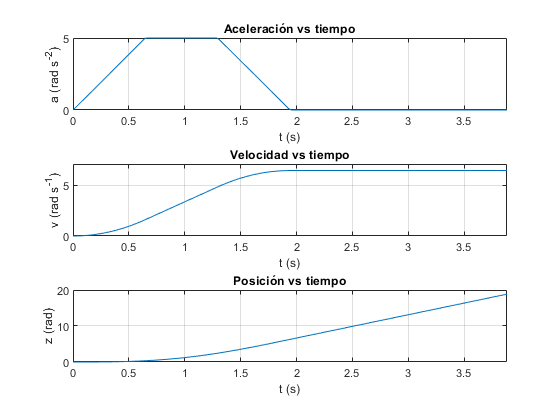

subplot(3,1,1)
plot(ts,aceleracion(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (rad s^{-2})')
xlim([0 double(2*Tgiro)])

subplot(3,1,2)
plot(ts,velocidad(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (rad s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 double(2*Tgiro)])

subplot(3,1,3)
plot(ts,posicion(ts))
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (rad)')
xlim([0 double(2*Tgiro)])


TablaCinematica=table(double(ts)',double(aceleracion(ts))',double(velocidad(ts))',double(posicion(ts))');
TablaCinematica.Properties.VariableNames=["Tiempo","Aceleracion","Velocidad","Posicion"]

TablaCinematica = 200×4 table
     Tiempo     Aceleracion    Velocidad     Posicion 
    ________    ___________    _________    __________

           0            0              0             0
    0.019514      0.15075      0.0014709    9.5676e-06
    0.039028      0.30151      0.0058836    7.6541e-05
    0.058541      0.45226       0.013238    0.00025832
    0.078055      0.60302       0.023534    0.00061232
    0.097569      0.75377       0.036772     0.0011959
     0.11708      0.90452       0.052952     0.0020666
      0.1366       1.0553       0.072074     0.0032817
     0.15611        1.206       0.094137     0.0048986
     0.17562       1.3568        0.11914     0.0069748
     0.19514       1.5075        0.14709     0.0095676
     0.21465       1.6583        0.17798      0.012734
     0.23417        1.809        0.21181      0.016533
     0.2

writetable(TablaCinematica,'Perfil_cinematica.txt','delimiter',' ', 'WriteVariableNames', true)
TablaTXT=table(double(ts)',double(velocidad(ts)*180/pi)');
writetable(TablaTXT,'Perfil_Velocidad.txt','delimiter',' ', 'WriteVariableNames', false)
clearvars -except Tgiro posicion aceleracion velocidad TablaCinematica

## Solución 

clear
syms t Theta_1(t) Theta_2(t) Theta_3(t) R_1(t)


syms r_1 r_1y r_2 r_3 x

syms V_r omega_1 omega_2 omega_3 theta_1 theta_2 theta_3 

syms a_r alpha_1 alpha_2 alpha_3


Vr_2=0.75

Vr_2 = 0.7500

Vr_3=1.70

Vr_3 = 1.7000

Vr_1y=0.45

Vr_1y = 0.4500


Vtheta_2=30*sym(pi)/180

$$Vtheta\_2 = \frac{\pi }{6}$$

Vomega_2=20

Vomega_2 = 20

Valpha_2=0

Valpha_2 = 0



Fc=sin(Theta_1)*R_1-r_1y;
Fc=simplify(Fc,'Steps',5)

$$Fc(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{\mathrm{1y}}$$


fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1])

$$fc(t) = r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}$$

SolR_1=solve(fc,r_1)

$$SolR\_1 = \frac{r_{\mathrm{1y}}}{\sin\left(\theta_{1}\right)}$$


Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5)

$$Fx(t) = r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)+r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)$$


fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-\frac{r_{\mathrm{1y}}\,\cos\left(\theta_{1}\right)}{\sin\left(\theta_{1}\right)}$$

fx=simplify(fx,'Steps',5)

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)$$

SolTheta_1=solve(fx,theta_1)

$$SolTheta\_1 = \mathrm{acot}\left(\frac{r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)}{r_{\mathrm{1y}}}\right)$$



Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5)

$$Fy(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)$$


fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fy = r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)$$


SolTheta_3=solve(fy,theta_3);
SolTheta_3=SolTheta_3(1)

$$SolTheta\_3 = \mathrm{asin}\left(\frac{r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)}{r_{3}}\right)$$


DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F1 = \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F2 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F3 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$



D2FcDt2=diff(DFcDt)

$$D2FcDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$

D2FxDt2=diff(DFxDt)

$$D2FxDt2(t) = \cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}$$

D2FyDt2=diff(DFyDt)

$$D2FyDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}+r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$


F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F4 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F5 = r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F6 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$


f(r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3)=[fc;fx;fy;F1;F2;F3;F4;F5;F6]

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ -\sigma_{1}+\sigma_{2}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

f=subs(f,[theta_2,r_1y,r_2,r_3,omega_2,alpha_2],[Vtheta_2,Vr_1y,Vr_2,Vr_3,Vomega_2,Valpha_2])

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10}\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\frac{17\,\omega_{3}\,\sin\left(\theta_{3}\right)}{10}-V_{r}\,\cos\left(\theta_{1}\right)-\frac{15}{2}\\ V_{r}\,\sin\left(\theta_{1}\right)-\frac{15\,\sqrt{3}}{2}-\frac{17\,\omega_{3}\,\cos\left(\theta_{3}\right)}{10}+\sigma_{3}\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-\frac{17\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-150\,\sqrt{3}-a_{r}\,\cos\left(\theta_{1}\right)-\frac{17\,\alpha_{3}\,\sin\left(\theta_{3}\right)}{10}+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)\\ -\sigma_{1}+\sigma_{2}+\frac{17\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-\frac{17\,\alpha_{3}\,\cos\left(\theta_{3}\right)}{10}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

f=simplify(f,'Steps',5)

$$f(r\_1, theta\_1, theta\_3, V\_r, omega\_1, omega\_3, a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10}\\ \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\frac{17\,\omega_{3}\,\sin\left(\theta_{3}\right)}{10}-V_{r}\,\cos\left(\theta_{1}\right)-\frac{15}{2}\\ V_{r}\,\sin\left(\theta_{1}\right)-\frac{15\,\sqrt{3}}{2}-\frac{17\,\omega_{3}\,\cos\left(\theta_{3}\right)}{10}+\sigma_{3}\\ V_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-\frac{17\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-150\,\sqrt{3}-a_{r}\,\cos\left(\theta_{1}\right)-\frac{17\,\alpha_{3}\,\sin\left(\theta_{3}\right)}{10}+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)\\ -\sigma_{1}+\sigma_{2}+\frac{17\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}}{10}-\frac{17\,\alpha_{3}\,\cos\left(\theta_{3}\right)}{10}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{4}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$



valTheta_3=subs(SolTheta_3,[theta_2,r_2,r_3,r_1y],[Vtheta_2,Vr_2,Vr_3,Vr_1y]);
ValTheta_1=subs(SolTheta_1,[theta_2,r_2,r_3,r_1y,theta_3],[Vtheta_2,Vr_2,Vr_3,Vr_1y,valTheta_3]);
valR_1=subs(SolR_1,[r_1y,theta_1],[Vr_1y,ValTheta_1]);


Jac=jacobian(f, [r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3])

JacInv=Jac^-1;

p1=[2 0.1 0.1 5 5 5 5 5 5]';
ValoresNR(1,:)=p1';

iteraciones=15;
for i=1:iteraciones
    p1=double(p1-JacInv(p1(1),p1(2),p1(3),p1(4),p1(5),p1(6),p1(7),p1(8),p1(9))*f(p1(1),p1(2),p1(3),p1(4),p1(5),p1(6),p1(7),p1(8),p1(9)));
    ValoresNR(i+1,:)=double(p1)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end

ValoresNR

ValoresNR =     2.0000    0.1000    0.1000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    3.5652    0.1473    0.0440   -5.2169   -3.7457   -7.7079 -182.4229   71.9543   77.0083
    2.2782    0.1801    0.0441   -7.2894   -1.0190   -7.6488 -393.1789   35.8392   90.9048
    2.4019    0.1889    0.0441   -6.8349    0.6281   -7.6488 -364.3695   32.7881   90.9049
    2.3906    0.1894    0.0441   -6.8024    0.5458   -7.6488 -358.7491   31.9270   90.9049
    2.3906    0.1894    0.0441   -6.8025    0.5454   -7.6488 -358.7333   31.9219   90.9049
    2.3906    0.1894    0.0441   -6.8025    0.5454   -7.6488 -358.7333   31.9219   90.9049


NormErrorNR'

ans =   212.4623
  214.3103
   29.0211
    5.6866
    0.0166
    0.0000


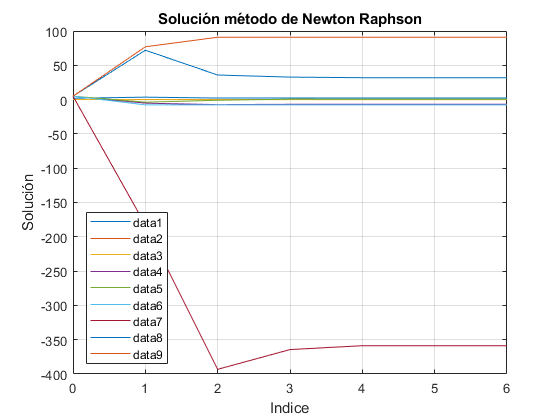

figure()
plot(0:(length(ValoresNR(:,1))-1),ValoresNR)
title('Solución método de Newton Raphson')
legend('show',"Location","best")
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresNR))
grid on

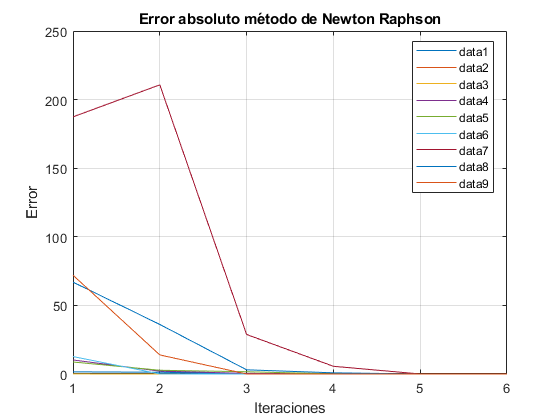

figure()
plot(ErrorNR)
title('Error absoluto método de Newton Raphson')
legend('show',"Location","best")
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on

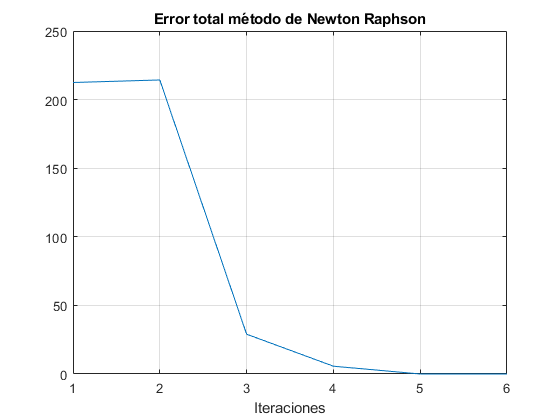

figure()
plot(NormErrorNR)
title('Error total método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on


SolNR=double(p1)

SolNR =     2.3906
    0.1894
    0.0441
   -6.8025
    0.5454
   -7.6488
 -358.7333
   31.9219
   90.9049


ErrorNRFinal=double(NormErrorNR(end))

ErrorNRFinal = 3.6567e-07